# Exploring Power Series

## Introduction

Power series are useful because they are essentially polynomials, which tend to be easier to work with than most other functions, such as trigonometric functions, exponentials and logarithms. They are used to expand and represent other functions, solve certain differential equations, approximate values of functions and are applied in all areas of engineering.

In this activity we will analyse the behaviour of power series and Taylor series by plotting partial sums. The main commands we will use are [`symsum`](https://au.mathworks.com/help/symbolic/symsum.html), [`fplot`](https://au.mathworks.com/help/matlab/ref/fplot.html) and [`taylor`](https://au.mathworks.com/help/symbolic/sym.taylor.html).

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

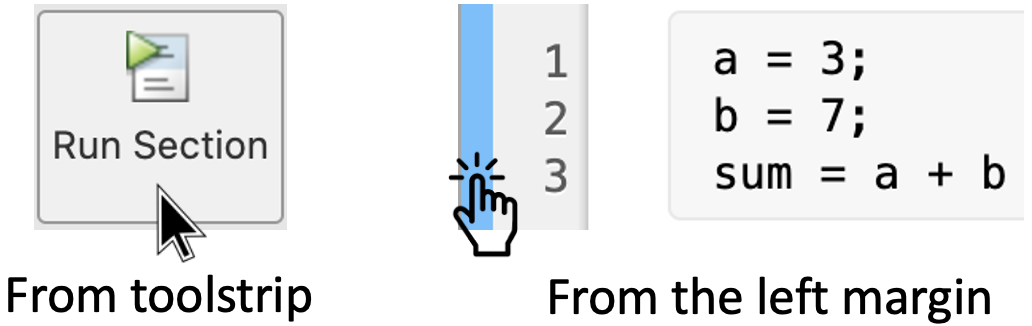

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Power series

A power series is a series of the form


$$\sum_{n=0}^{\infty } c_n {\left(x-a\right)}^n =c_0 +c_1 \left(x-a\right)+c_2 {\left(x-a\right)}^2 +\cdots$$


### 1.1 The geometric series

Consider the series 


$$\sum_{n=0}^{\infty } x^n =1+x+x^2 +\cdots +x^n +\cdots$$


This is known as the *geometric series* and it is well known that it diverges when $|x|\ge 1$ and converges when $-1<x<1$, that is


$$\sum_{n=0}^{\infty } x^n =\frac{1}{1-x}$$


We can analyse this equation geometrically by plotting a few elements of the sequence of partial sums $s_n \left(x\right)=1+x+x^2 +\cdots +x^n$.

Recall that the sum of a power series is the limit of the sequence of partial sums. That is


$$\frac{1}{1-x}=\lim_{n\to \infty } s_n \left(x\right)$$


Thus, as $n$ increases, $s_n(x)$ becomes a better approximation to $\frac{1}{1-x}$.

Let's plot a few terms of the sequence $s_n(x)$ of partial sums. First, we need two symbolic variables:

syms x n

Now we define a few partial sums using the command [`symsum`](https://au.mathworks.com/help/symbolic/symsum.html):

s2 = symsum(x^n, n, 0, 2);    % 1 + x + x^2
s5 = symsum(x^n, n, 0, 5);    % 1 + x + x^2 + x^3 + x^4 + x^5
s11 = symsum(x^n, n, 0, 11);  % 1 + x + ... + x^(11)
L = 1/(1-x);                  % We also define the sum to compare

Finally we plot these with the commands [`fplot`](https://au.mathworks.com/help/matlab/ref/fplot.html) and [`hold`](https://au.mathworks.com/help/matlab/ref/hold.html) to compare them with the function $\frac{1}{1-x}$ :

fplot([s2 s5 s11],'Linewidth',1)  % Multiple graphs in the same plot must be inside "[]"

hold on                           % This command allows us to add an extra graph in the same plot

fplot(L,'--ok')                   % Plot the function 1/(1-x) with a dashed line & circle

legend('show','Location','best')  % Label each graph to identify them
title('Approximation of Geometric series')
axis([-3 3 -15 15]), grid on

hold off                          % We turn off the "hold" command

Run this section to see the output. Observe how the partial sums behave within the interval $-1<x<1$. Then modify the code to add the partial sums $s_{16}(x)$ and $s_{30}(x)$ and re-run this section. What do you notice? Do they approximate better to the function $\frac{1}{1-x}$  in the interval $-1<x<1$?

### 1.2 Taylor series

Recall that if $f$ has a power series representation at $a$, that is, if 

$f(x)=\displaystyle\sum_{n=0}^{\infty} c_n(x-a)^n$, with $|x-a|<R$

then its coefficients are given by the formula


$$c_n=\frac{f^{(n)}(a)}{n!}$$


Thus, we have the formula

$f(x)=\displaystyle\sum_{n=0}^{\infty} \frac{f^{(n)}(a)}{n!}(x-a)^n$, with $|x-a|<R$

known as the *Taylor series of the function* $f$ about $a$. For the special case $a=0$ we have the Maclaurin series

$f(x)=\displaystyle\sum_{n=0}^{\infty} \frac{f^{(n)}(0)}{n!}x^n = f(0) + \frac{f'(0)}{1!}x+ \frac{f'(0)}{2!}x^2+\cdots$, with $|x|<R$.

A *Taylor polynomial, *or *expansion,* of degree $n$ is defined as the partial sum


$$T_n(x)=\displaystyle\sum_{k=0}^{n}\frac{f^{(k)}(a)}{k!}(x-a)^k$$


In MATLAB we can easily calculate Taylor polynomials using the command:

where `f` is the function, x is the symbolic variable, `a` is the point around which the expansion is made, and n is the degree of the Taylor polynomial.

#### 1.2.1 Calculating terms of the Taylor series

For example, let's find the Taylor expansions of degrees 2, 3, 4 and 5 around $x=1$ for $f(x)=\log(x)$. Thus we write:

syms x
f = log(x);
taylor(f, x, 1, 'Order', 2)  % Taylor Pol. of degree 1
taylor(f, x, 1, 'Order', 3)  % Taylor Pol. of degree 2
taylor(f, x, 1, 'Order', 4)  % Taylor Pol. of degree 3
taylor(f, x, 1, 'Order', 5)  % Taylor Pol. of degree 4

Run this section and analyse the different outputs. Are these expansions correct? How can you verify these results? 

Now let's find the Taylor expansions of degrees 1, 3, 5 and 7 around $x=0$ for $f(x)=\sin(x)$. Even orders are omitted since Taylor polynomials for $\sin(x)$ have no even order terms. In this case we have to use the values 2, 4, 6 and 8 in the command `taylor`. That is:

syms x
g = sin(x);
taylor(g, x, 0, 'Order', 2)
taylor(g, x, 0, 'Order', 4)
taylor(g, x, 0, 'Order', 6)
taylor(g, x, 0, 'Order', 8)

Run this section to analyse the results. Then change the values 2, 4, 6 and 8 to 1, 2, 3, and 5 and re-run this section to see what happens.

#### 1.2.2 Potting terms of the Taylor series

We can also analyse geometrically how the Taylor expansions approximate to a given function. For example, let's calculate a few terms of the Taylor series for

$f(x)=\displaystyle\frac{\sin x}{x}$  around $x=0$.

The following code plots the original function $f$ and its Taylor expansions `T4`, `T6`, and `T10`, of degrees 4, 6, and 10.

clear  % This command just clears all previous variables
syms x
f = sin(x)/x;   % Define function

T4 = taylor(f, x, 0, 'Order', 5)   % Taylor Pol. of degree 4
T6 = taylor(f, x, 0, 'Order', 7)   % Taylor Pol. of degree 6
T10 = taylor(f, x, 0, 'Order', 11) % Taylor Pol. of degree 10

fplot([T4 T6 T10],'Linewidth',1)   % Plot all the Taylor expansions

hold on

fplot(f,'--ok')                    % Plot sin(x)/x with a dashed line & circle

axis([-6 6 -1 1]), grid on
legend('show','Location','Best')
title('Taylor Series Expansion')

hold off

Run this section to see the different graphs of the Taylor expansions. Notice that as $n$ increases, $T_n(x)$ appears to approach to $\sin x/x$. This suggests that $\sin x/x$ is equal to the sum of its Taylor series.

## 2. Hands on practice

Let's practice what we just learned.

### Activity 1:

Consider the *Bessel function of order zero*


$$J_0(x)= \displaystyle \sum_{n=0}^{\infty} \frac{(-1)^{n}x^{2n}}{2^{2n}(n!)^2}$$


This series converges for all values of $x$ (this can be determined by the Ratio Test). $J_0(x)$ can be defined in MATLAB using the command `bessel(n, x)`, where `n` indicates the order and `x` the symbolic variable. That is:

You task will be to plot the first four terms of the sequence of partial sums and the [Bessel function](https://au.mathworks.com/help/matlab/ref/besselj.html) provided by MATLAB. See example in section 1.1.

To do this you must complete the following code:

syms x n
J0 = besselj(0,x)

% 1. Define the first four partial sums using the command "symsum"

%{---Replace this comment with code---%}

% 2. Use the command "fplot" (see section 1.1)

%{---Replace this comment with code---}%


**Hint:** To calculate $n!$ you can use the MATLAB function [`factorial(n)`](https://au.mathworks.com/help/matlab/ref/factorial.html).

Run your code and analyse the result. What do you notice? What do you wonder? Do the partial sums approximate to the Bessel function provided by MATLAB?

### Activity 2:

Consider the function


$$f(x)=\frac{x^2}{x^2+1}$$


Calculate the Taylor polynomials of degrees 2, 4, 6 and 12 around $x=0$ with the command [`taylor`](https://au.mathworks.com/help/symbolic/sym.taylor.html) (Verify the first two terms in your notebook). Then plot them together with $f$ to compare. See section 1.2.2.

Write your code here:

Run your code and analyse the output.